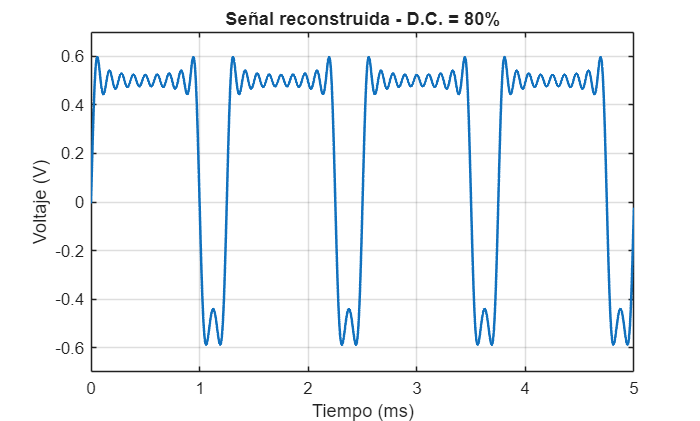

clc;
clear;
close all;

% Parámetros de la señal
Vp = 0.5;
f0 = 800;
D = 0.8;

% Vector de tiempo (5 ms)
t = 0:1e-6:(5e-3-1e-6);

% Componente DC
Vdc = Vp*(2*D - 1);

% Inicializar señal
v = Vdc;

% Reconstrucción con 11 armónicos
for n = 1:11

    % Coeficientes de Fourier
    an = (2*Vp/(n*pi))*sin(2*pi*n*D);
    bn = (2*Vp/(n*pi))*(1-cos(2*pi*n*D));

    v = v + an*cos(2*pi*n*f0*t) ...
          + bn*sin(2*pi*n*f0*t);

end

% Dominio del tiempo
figure;
plot(t*1000,v,'LineWidth',1.5);
grid on;
xlabel('Tiempo (ms)');
ylabel('Voltaje (V)');
title('Señal reconstruida - D.C. = 80%');
xlim([0 5]);
ylim([-0.7 0.7]);

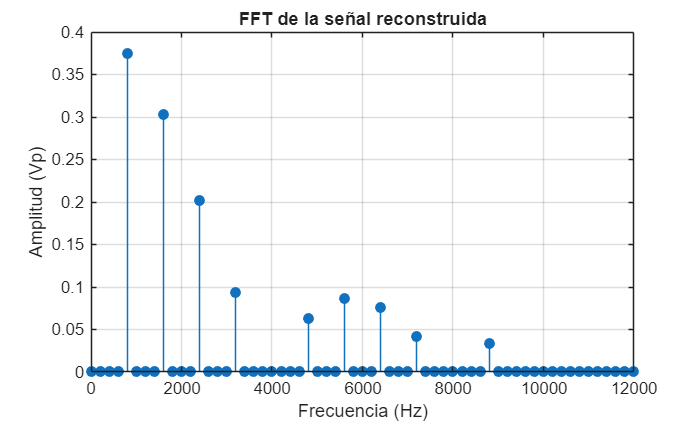


% Dominio de la frecuencia
Fs = 1/(t(2)-t(1));
N = length(v);

Y = fft(v-mean(v));

P2 = abs(Y)/N;
P1 = P2(1:N/2+1);
P1(2:end-1) = 2*P1(2:end-1);

f = Fs*(0:N/2)/N;

figure;
stem(f,P1,'filled');
grid on;
xlabel('Frecuencia (Hz)');
ylabel('Amplitud (Vp)');
title('FFT de la señal reconstruida');
xlim([0 12000]);